# Taller IX

### 23/05/2022 2022-01S

#### Métodos Númericos

#### *Resumen sobre la semana 8 y 9*

*Notas para el uso de MATLAB:*

- Frente a las operaciones de númericas tenemos 2 definiciones distintas y es importante separarlas, las operaciones $+-*\;/$, son directas matriciales, en cambio las prefijadas con ${\prime \ldotp }^{\prime }$, son *element-wise*, o sea se realizan en cada uno de los elementos del argumento entregado a la función. Importante en la notación con @

- Si se necesita conocer información sobre un método o sobre alguna rutina, es comando `help ``rutina` resulta bastante útil.

#### Integración Númerica

Para el taller de esta semana se solucionan dos de las seis integrales presentes, y dos de los cuatro ejercicios en $9\;y\;10$ del taller 9, se propone el uso de los métodos integrales y las propias herramientas de Matlab

**9) **Considere las siguientes funciones:


$$\begin{array}{l}
f\left(x\right)=\sin \left(x^2 \right)\;\cos \left(e^{2x} \right)\;\;:\;\;x\in \left\lbrack -2,1\right\rbrack \\
f\left(x\right)=\sin \left(\cos \left(e^{2\;x} \right)\right)\;\;\;\;\;\;\;:\;x\in \left\lbrack -5,1\right\rbrack \\
f\left(x\right)=\frac{1}{1+12\;x^2 }\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;:\;x\in \left\lbrack -4,2\right\rbrack \\
f\left(x\right)=\frac{\cos \left(x\right)}{\ln \left(e^x +15\right)}\;\;\;\;\;\;\;\;\;\;\;:\;x\in \left\lbrack -1,11\right\rbrack \\
f\left(x\right)=\frac{\sin \left(x\right)}{\sqrt{x^2 +5}}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;:\;x\in \left\lbrack 0,7\pi \right\rbrack 
\end{array}$$


Aproximar el  valor de $\int_a^b f\left(x\right)\;\mathrm{dx}$ por medio de la cuadratura de Gauss-Legendre con 2, 3, 4, 5, 6 nodos.

clear
syms f(x)

f1(x) = sin(x^2) * cos(exp(2*x));
f2(x) = sin(cos(exp(2*x)));
f3(x) = 1 / (1 + 12*x^2);
f4(x) = cos(x) / log(exp(x) + 15);
f5(x) = sin(x) / sqrt(x^2 + 5);

f1 = matlabFunction(f1);
f2 = matlabFunction(f2);
f3 = matlabFunction(f3);
f4 = matlabFunction(f4);
f5 = matlabFunction(f5);

[quad, raices, nodos, coefs] = GaussLegendre(f5, 0, 7*pi, 3)
(7*pi - 0)/ 2 * fliplr(coefs)' * f5(nodos)
GaussLegendre(f1, -2, 1, 10), integral(f1, -2, 1)
GaussLegendre(f2, -5, 1, 20), integral(f2, -5, 1)
GaussLegendre(f3, -4, 2, 10), integral(f3, -4, 2)
GaussLegendre(f4, -1, 11, 10), integral(f4, -1, 11)
GaussLegendre(f5, 0, 7*pi, 10), integral(f5, 0, 7*pi)

**10) **Calcule el valor de las siguientes integrales impropias


$$\int_0^5 \frac{1}{\sqrt{x}}\mathrm{dx},\;\;\;\int_1^{\infty } e^{-x^2 } \;\mathrm{dx},\;\;\;\;\int_{-1}^{\infty } \frac{\sin^2 \left(y\right)}{e^y }\mathrm{dy},\;\;\;\int_2^{\infty } \frac{1}{\left(1\;+y^2 \right)\left(1+0\ldotp 5y^2 \right)}\mathrm{dx}$$
 

clear
syms f(x)


quad = 0.4470

raices =    -0.7746
    0.0000
    0.7746


nodos =     2.4784
   10.9956
   19.5127


coefs =     0.5556
    0.8889
    0.5556


f1(x) = 1 / sqrt(x);

ans = 0.4470

f2(x) = exp(-x^2);

ans = 0.8073

ans = 0.8069

f3(x) = sin(x)^2 / exp(x);

ans = 4.0314

ans = 4.0340

f4(x) = 1 / ((1 + x^2)* (1 + .5 * x^2));

ans = 0.6999

ans = 0.8447

ans = 0.2187

ans = 0.2187

f1 = matlabFunction(f1);

ans = 0.5321

ans = 0.5314

f2 = matlabFunction(f2);
f3 = matlabFunction(f3);
f4 = matlabFunction(f4);

GaussLegendre(f1, 0, 5, 40)

### Otros ejemplos sobre integración Númerica

El tema es un tanto denso, por lo que se proponen ejercicios extras con los que podemos repasar los conceptos vistos:

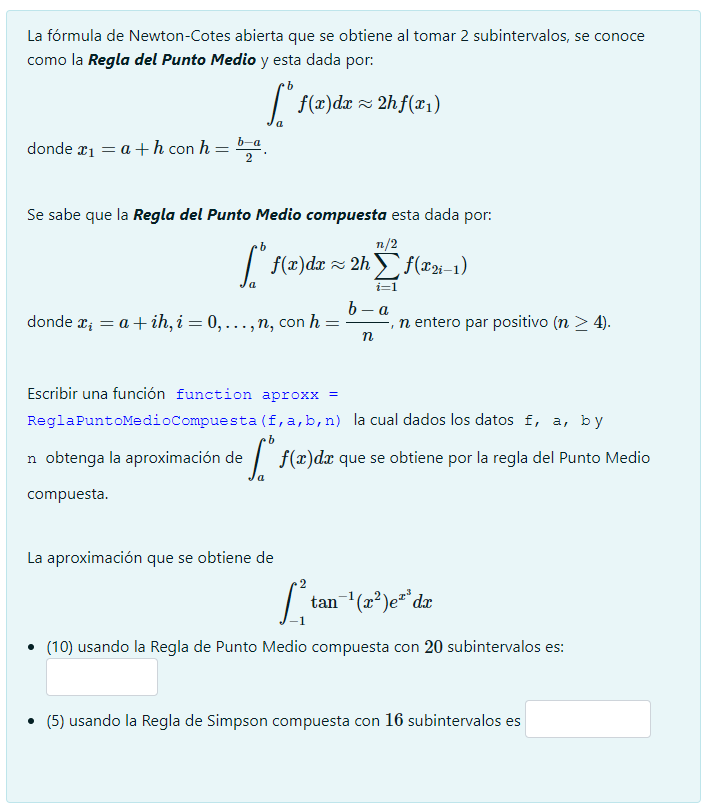

Cálcular el valor de la integral:


$$\int_{-\infty }^{\infty } e^{-x^2 } \;\tan^{-1} \left(3x-1\right)\;\mathrm{dx}$$


### Solución númerica de ecuaciones diferenciales ordinarias

Para el taller de esta semana se solucionan dos ejercicios: $\left.\left.2\ldotp b\right)\;y\;c\right),y\;3\ldotp$

**2) **Determine las constantes de Lipschitz validas para todo $|t|\le 1$ para las siguientes funciones:


$$\begin{array}{l}
f\left(t,y\right)=t^4 \;y\\
f\left(t,y\right)=t\;e^{-y^2 } 
\end{array}$$


**3) **Utilice el método de Euler para resolver los problemas de valor inicial siguientes con los valores de $h$ indiciados. Como la solución correcta se conoce, tambien el error que se incurre:


$$\begin{array}{l}
y^{\prime } =\frac{y}{t}-{\left(\frac{y}{t}\right)}^2 ,\;\;1\le t\le 2,\;y\left(2\right)=1,\;h=0\ldotp 1\\
y^* \left(t\right)=\frac{t}{1+\ln \left(t\right)}
\end{array}$$



$$\begin{array}{l}
y^{\prime } =-\;\left(y+1\right)\;\left(y+3\right),\;\;0\le t\le 2,\;\;\;y\left(0\right)=-2,\;\;h\;=0\ldotp 2\\
y^* \left(t\right)=-3+\frac{2}{1+e^{-2\;t} }
\end{array}$$


ans = 4.4241